# Spike Time Analysis

## Download and extract data

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
download_from_sciebo("https://uni-bonn.sciebo.de/s/3Uf2gScrvuTPQhB", 'data/steinmetz_2017-01-08_Muller.nc')

Done!

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))

spike_id = ncread("data/steinmetz_2017-01-08_Muller.nc","spike_id");
spike_time = ncread("data/steinmetz_2017-01-08_Muller.nc","spike_time");
spike_cell = ncread("data/steinmetz_2017-01-08_Muller.nc","spike_cell");
spike_trial = ncread("data/steinmetz_2017-01-08_Muller.nc","spike_trial");


data = table(spike_id, spike_time, spike_cell, spike_trial)

data = 1836009×4 table
    spike_id    spike_time    spike_cell    spike_trial
    ________    __________    __________    ___________

        1         2.3629          1              1     
        2         2.3849          1              1     
        3         1.4507          1              2     
        4         1.4596          1              2     
        5         1.9635          1              2     
        6         1.9653          1              2     
        7         1.9708          1              2     
        8         1.9727          1              2     
        9         1.9751          1              2     
       10         1.9776          1              2     
       11         1.5432          1              6     
       12         1.5456          1              6     
       13         1.5476          1              6     


**Example Exercise**

How many cells spiked during trial 1?

spike_cells_selected_trial = data(data.spike_trial==1,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 860

**Exercises**

How many cells spiked during trial 24?

spike_cells_selected_trial = data(data.spike_trial==24,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 830

How many cells spiked during the last trial?

last_trial = data.spike_trial(height(data))

last_trial = uint32
252

spike_cells_selected_trial = data(data.spike_trial==last_trial,'spike_cell');
height(unique(spike_cells_selected_trial))

ans = 919

Make a list of the number of spiking cells of each trial. **Hint** - use  `groupsummary(data, "coulum_A", "numunique", "coulmn_B")`

Name the result `n_spiking_cells`

n_spiking_cells = groupsummary(data, "spike_trial","numunique", "spike_cell").numunique_spike_cell

n_spiking_cells =    860
   839
   809
   879
   836
   848
   824
   853
   796
   804


What was the maximum number of spiking cells?

max(n_spiking_cells)

ans = 1001

Let's visualize the distribution of the number of spiking cells with a histogram.

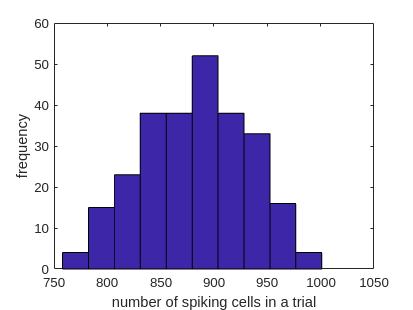

hist(n_spiking_cells)
xlabel('number of spiking cells in a trial')
ylabel('frequency')

What is the minimum number of spiking cells? Compare this value to the histogram above

min(n_spiking_cells)

ans = 758

## Visualize the spiking activity using spike times

**Example Exercise**

Create a scatter plot to visualize spikes for a single neuron across multiple trials.

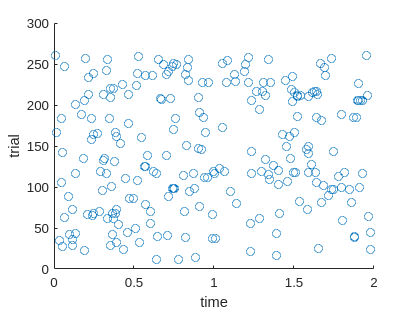

dd = data(data.spike_cell==12,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

**Exercises**

Create a scatter plot to visualize spikes for a neuron number 11 across multiple trials.

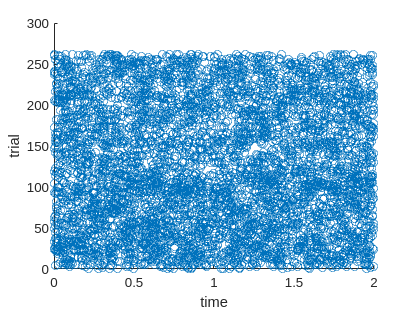

dd = data(data.spike_cell==11,:);
scatter(dd.spike_time, dd.spike_trial)
xlabel('time')
ylabel('trial')

Wow, that plot looks crowded! Instead of a circle,  plot with `|`. Use `help scatter` to find out out how

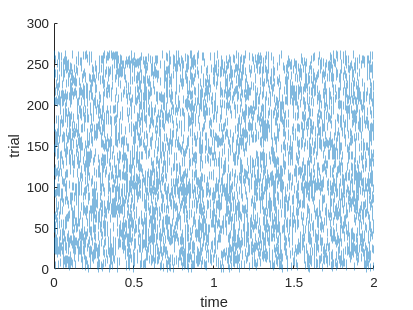

dd = data(data.spike_cell==11,:);
scatter(dd.spike_time, dd.spike_trial, "|")
xlabel('time')
ylabel('trial')

Create a scatter plot to visualize spikes for all neurons in trial 83.

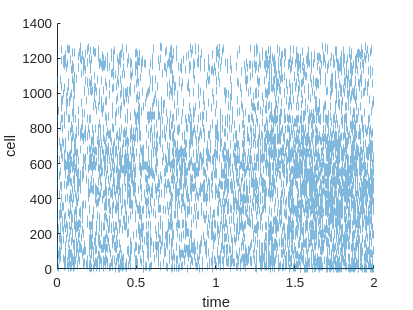

dd = data(data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, "|")
xlabel('time')
ylabel('cell')

help scatter

  scatter Scatter plot.
     scatter(X,Y) creates a scatter plot with markers at the locations
     specified by X and Y. One scatter object is created when X and Y are
     vectors. Multiple scatter plots are created if X or Y are matrices.
 
     scatter(X,Y,SZ) specifies the area of each marker in points squared.
     To plot all markers with the same size, specify SZ as a scalar. To
     plot each marker with a different size, specify SZ as a vector or
     matrix. If SZ is an empty vector, the default size is used.
 
     scatter(X,Y,SZ,C) specifies the marker colors. To plot all markers
     with the same color, specify C as a color name or an RGB triplet. To
     specify different colors for each scatter plot, specify C as an 
     m-by-3 matrix of RGB triplets with one color per scatter object. To
     specify different colors for each scatter point when a single scatter
     plot is created, specify C as an m-

We can vary the color of the points based of the spike time with the 4th argument of `scatter. `**Hint - **the 3rd argument will have to be empty - `[]`

Remake the above plot setting the color of the points to the spike time.

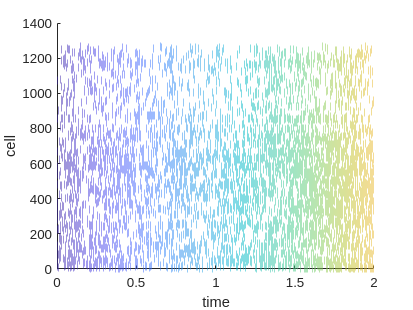

dd = data(data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, [], dd.spike_time,"|")
xlabel('time')
ylabel('cell')

Remake the plot above, giving the plot an appropriate title

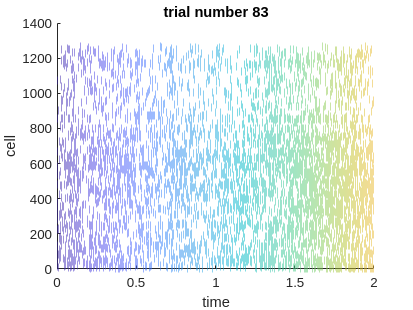

dd = data(data.spike_trial==83,:);
scatter(dd.spike_time, dd.spike_cell, [], dd.spike_time,"|")
xlabel('time')
ylabel('cell')
title('trial number 83')

## Relating spike timing to event-based variables

## Spiking activity in different brain areas